% Calc CIE for all images
path = "C:\Users\gayat\Documents\TNM097\Projekt\database_rescaled";
filePattern = fullfile(path, '*.jpg'); 
theFiles = dir(filePattern);
nrOfImages = length(theFiles);

databaseImageCIEs = zeros(nrOfImages,1,3);

for k = 1 : nrOfImages
    % Load next image
    fullFileName = fullfile(theFiles(k).folder, theFiles(k).name);
    Image = im2double(imread(fullFileName));
    databaseImageCIEs(k,1,:) = calcCIE(Image);
end

save("databaseImageCIEs", "databaseImageCIEs")



n = 30;

image = imread("hallon.jpg");
calcCIE(image)

ans = 	1.0e+03 *

    4.9489   -0.4911    2.2223


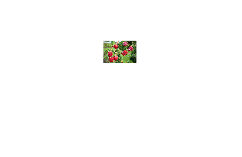

imshow(image)

reproduce(image,n)


% clear
% path = "C:\Users\gayat\Documents\TNM097\Projekt\database";
% filePattern = fullfile(path, '*.jpg'); 
% theFiles = dir(filePattern);
% n = 30;
% 
% nrOfImages = length(theFiles);
% databaseCIE = zeros(nrOfImages,3)
% 
% for k = 1 : nrOfImages
% 
%     % Load next image
%     baseFileName = theFiles(k).name;
%     fullFileName = fullfile(theFiles(k).folder, baseFileName);
%     Image = im2double(imread(fullFileName));
%     
%     % Resize and save im
%     imSize = size(Image);
%     shorter = imSize(:,2);
%     longer = imSize(:,1);
% 
%     if shorter > longer
%         temp = shorter;
%         shorter = longer;
%         longer = temp;
%     end
% 
%     Image = Image(1:shorter, 1:shorter, :);
% 
%     Image = imresize(Image, [n, n]);
%     imwrite(Image, "database_rescaled\" + baseFileName);
% 
% 
%     % Save CIE value of image
%     CIE = calcCIE(Image);
%     databaseCIE(k,:) = CIE;
% end
% 
% save("databaseCIE", "databaseCIE")
